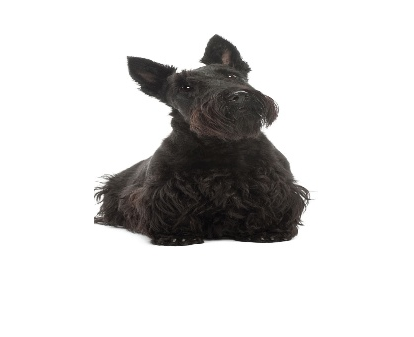

imdsTrain = imageDatastore('train', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
imdsTest = imageDatastore('test', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% visualize a random image
I = readimage(imdsTrain,randi(numel(imdsTrain.Files)));
imshow(I);

net = googlenet;

k = imresize(I,[224,224]);
inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsTest,"ColorPreprocessing","gray2rgb");

% pull a test sample
test_sample_table = augimdsTrain.readByIndex(1);
test_sample = test_sample_table.input{1};

% use GoogLeNet to classify image
label = classify(net,test_sample)

label = categorical
     Sussex spaniel 


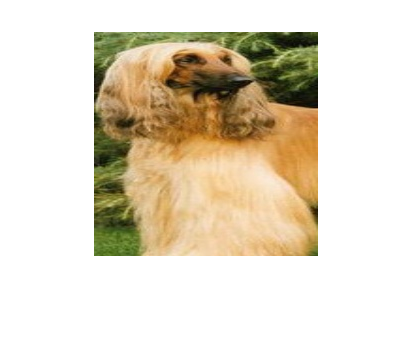

imshow(test_sample);

## Step #3: Transfer Learning

Transfer learning involves modifying an existing network to work for new data. The final layers need to be replaced in order to work with this dataset. For larger datasets, training a network can take a long time. This should train relatively quickly in a few minutes. 

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |        0.00% |       5.7786 |          0.0003 |
|       1 |          50 |       00:01:57 |       40.00% |       3.0189 |          0.0003 |
|       1 |         100 |       00:03:27 |       40.00% |       1.8047 |          0.0003 |
|       1 |         150 |       00:04:53 |       80.00% |       0.8833 |          0.0003 |
|       1 |         200 |       00:06:16 |       90.00% |       0.4437 |          0.0003 |
|       1 |         250 |       00:07:47 |       80.00% |       0.6854 |          0.0003 |
|       1 |         300 |  

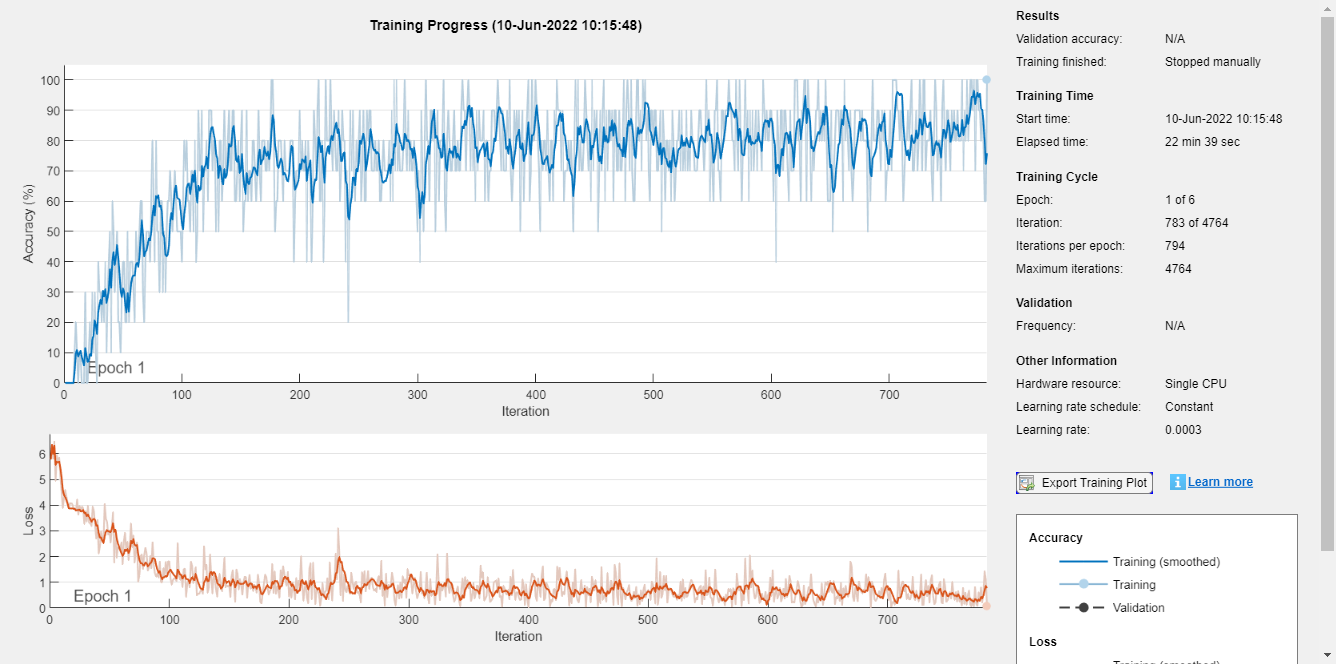

lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Plots','training-progress');

newNet = trainNetwork(augimdsTrain,lgraph,options);

[YPred,probs] = classify(newNet,augimdsValidation);
accuracy = mean(YPred == imdsTest.Labels)

% And view individual images

idx = randperm(numel(imdsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end
